load("count_data.mat")
k = size(trainx,1);
p = 2;
x0 = zeros(k*p, size(trainx, 2));
xn = zeros(k*p, size(testx, 2));

for i = 1 : p
    for j = 1 : k
        x0((i-1)*k+1,:) = trainx(j,:) .^ i;
    end
end

theta_LS = funLS(x0, trainy);

theta =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


theta_RLS = funRLS(x0, trainy);
theta_LASSO = funLASSO(x0, trainy);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping cr

theta_RR = funRR(x0, trainy);


Optimal solution found.



[var_BR, mean_BR] = funBR(x0, trainy);

for i = 1 : p
    for j = 1 : k
        xn((i-1)*k+1,:) = testx(j,:) .^ i;
    end
end

y0_LS = xn' * theta_LS;
y0_RLS = xn' * theta_RLS;
y0_LASSO = xn' * theta_LASSO;
y0_RR = xn' * theta_RR;
y0_BR = xn' * mean_BR;
var_fin = xn' * var_BR * xn;

mae_LS = mean(abs(y0_LS - testy));
mae_RLS = mean(abs(y0_RLS - testy));
mae_LASSO = mean(abs(y0_LASSO - testy));
mae_RR = mean(abs(y0_RR - testy));
mae_BR = mean(abs(y0_BR - testy));

mse_LS = mean((y0_LS - testy) .^ 2);
mse_RLS = mean((y0_RLS - testy) .^ 2);
mse_LASSO = mean((y0_LASSO - testy) .^ 2);
mse_RR = mean((y0_RR - testy) .^ 2);
mse_BR = mean((y0_BR - testy .^ 2));

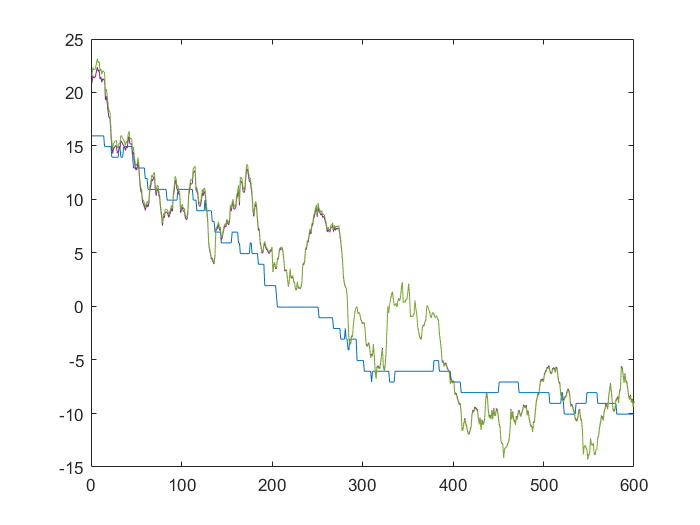

yy = [testy, y0_LS, y0_RLS, y0_LASSO, y0_RR];
figure
plot(yy);